# Ler os dados

clear; clc; close all;

serie = load('serie_tempo_ftcs.dat');
data = load('ftcs.dat');        

tempo = serie(:, 1);
T_centro = serie(:, 2);
T_max = serie(:, 3);

# Reconstruir malha

Nx = 100;
Ny = 100;

x = data(:,1);
y = data(:,2);
T = data(:,3);

X = reshape(x, Ny, Nx)';  
Y = reshape(y, Ny, Nx)';
Temp = reshape(T, Ny, Nx)';

# Inércia Térmica (Série Temporal)

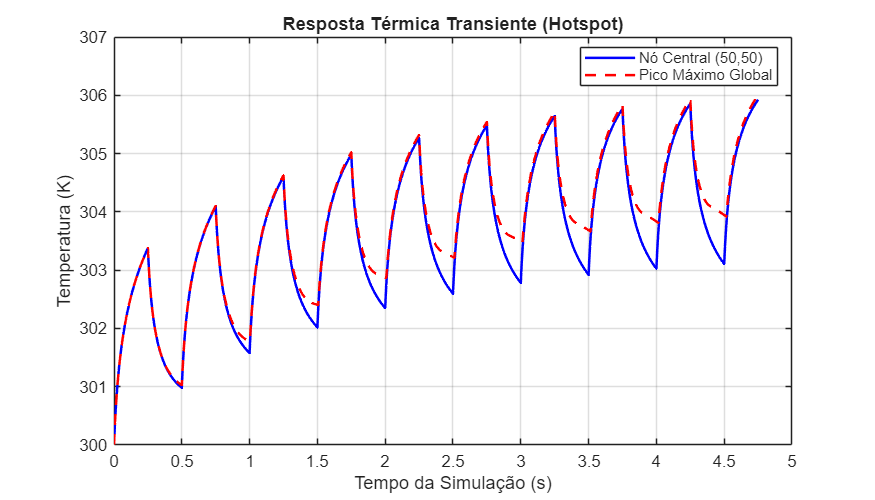

figure('Name', '1. Transiente Térmico', 'Position', [100, 100, 700, 400]);
plot(tempo, T_centro, 'b-', 'LineWidth', 1.5); hold on;
plot(tempo, T_max, 'r--', 'LineWidth', 1.5);
title('Resposta Térmica Transiente (Hotspot)');
xlabel('Tempo da Simulação (s)');
ylabel('Temperatura (K)');
legend('Nó Central (50,50)', 'Pico Máximo Global', 'Location', 'best');
grid on;

# Superfície 3D

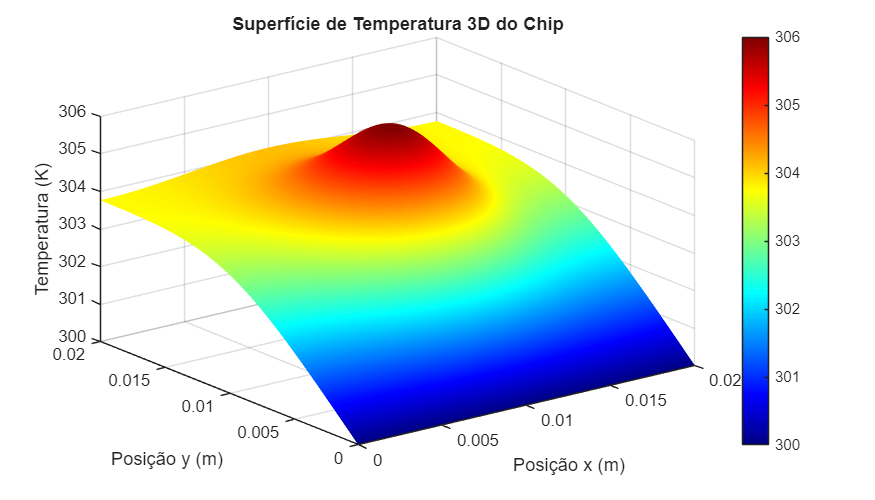

figure('Name', '2. Superfície 3D', 'Position', [150, 150, 700, 400]);
surf(X, Y, Temp);
shading interp;
colormap(jet); 
colorbar;
xlabel('Posição x (m)');
ylabel('Posição y (m)');
zlabel('Temperatura (K)');
title('Superfície de Temperatura 3D do Chip');

# Gráfico de Perfil

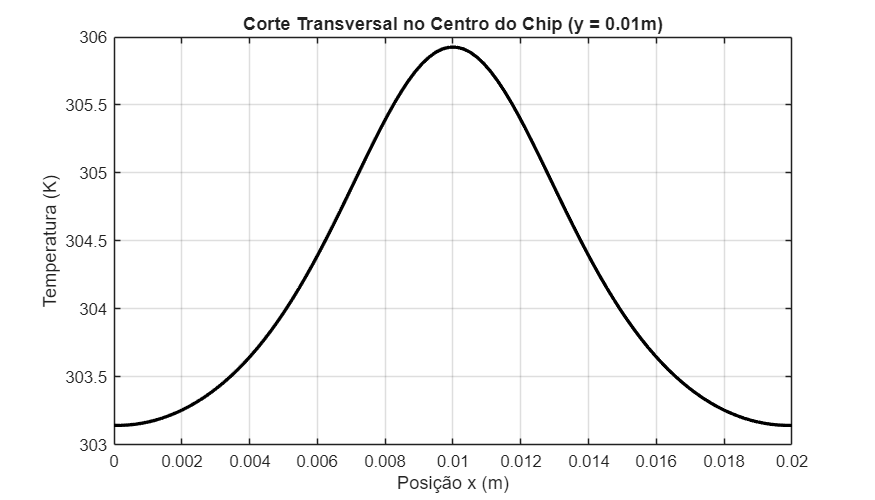

figure('Name', '3. Perfil Transversal', 'Position', [200, 200, 700, 400]);
plot(X(:, 50), Temp(:, 50), 'k-', 'LineWidth', 2);
xlabel('Posição x (m)');
ylabel('Temperatura (K)');
title('Corte Transversal no Centro do Chip (y = 0.01m)');
grid on;

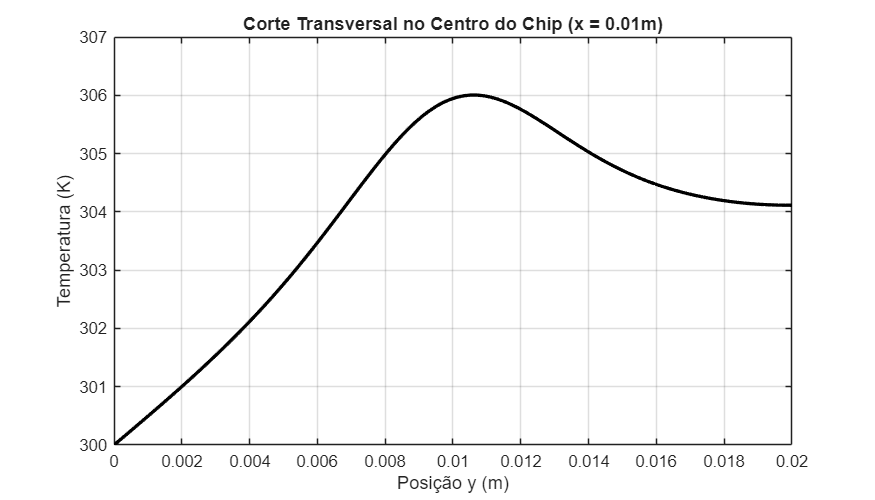

figure('Name', '3. Perfil Transversal (Eixo Y)', 'Position', [200, 200, 700, 400]);
plot(Y(50, :), Temp(50, :), 'k-', 'LineWidth', 2);
xlabel('Posição y (m)');
ylabel('Temperatura (K)');
title('Corte Transversal no Centro do Chip (x = 0.01m)');
grid on;

# Mapa de Calor

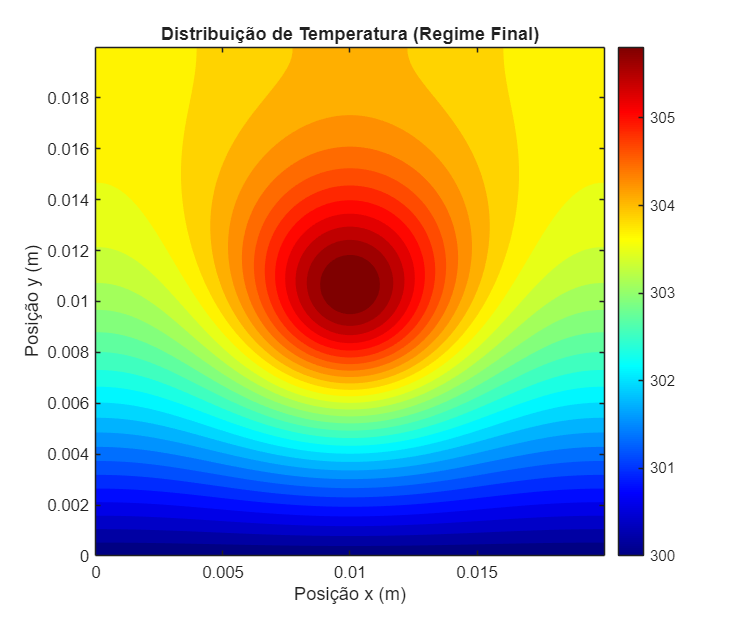

figure('Name', '4. Mapa de Calor (Top-Down)', 'Position', [250, 250, 600, 500]);
contourf(X, Y, Temp, 30, 'LineColor', 'none');
colormap(jet);
colorbar;
xlabel('Posição x (m)');
ylabel('Posição y (m)');
title('Distribuição de Temperatura (Regime Final)');
axis equal; tightval = axis; axis(tightval);

# Estudo de Convergência

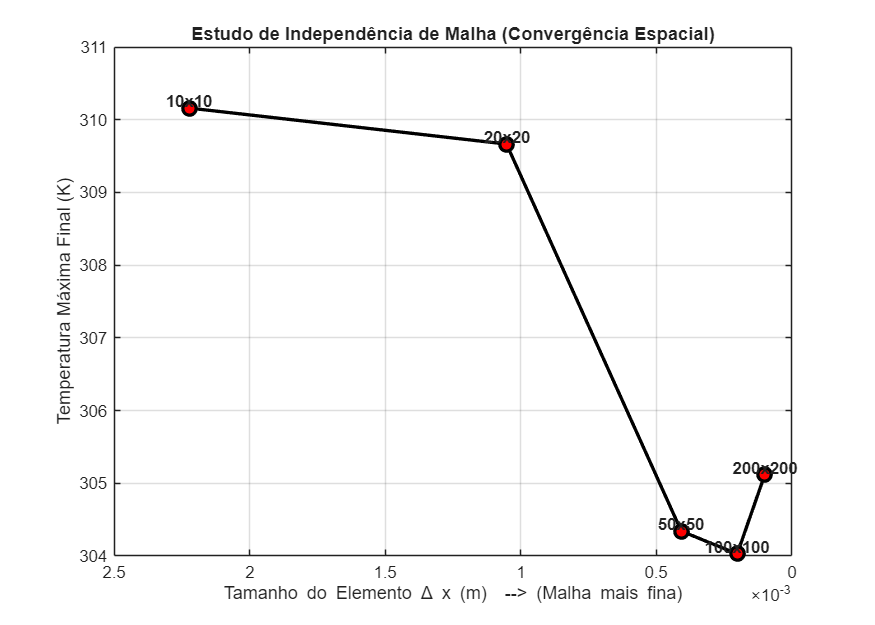

T_max_resultados = [310.1601, 309.6651, 304.3419, 304.02932521349237, 305.1169]; 

N_nos = [10, 20, 50, 100, 200]; 
Lx = 0.02;
dx_valores = Lx ./ (N_nos - 1);

figure('Name', 'Estudo de Convergencia', 'Position', [150, 150, 700, 500]);

plot(dx_valores, T_max_resultados, '-ko', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'r');

set(gca, 'XDir', 'reverse'); 

title('Estudo de Independência de Malha (Convergência Espacial)');
xlabel('Tamanho do Elemento \Delta x (m)  --> (Malha mais fina)');
ylabel('Temperatura Máxima Final (K)');
grid on;

for i = 1:length(N_nos)
    texto = sprintf('%dx%d', N_nos(i), N_nos(i));
    text(dx_valores(i), T_max_resultados(i) + 0.1, texto, ...
        'HorizontalAlignment', 'center', 'FontSize', 10, 'FontWeight', 'bold');
end